P=110:-0.05:95 %单位kPa

P =   110.0000  109.9500  109.9000  109.8500  109.8000  109.7500  109.7000  109.6500  109.6000  109.5500  109.5000  109.4500  109.4000  109.3500  109.3000  109.2500  109.2000  109.1500  109.1000  109.0500  109.0000  108.9500  108.9000  108.8500  108.8000  108.7500  108.7000  108.6500  108.6000  108.5500  108.5000  108.4500  108.4000  108.3500  108.3000  108.2500  108.2000  108.1500  108.1000  108.0500  108.0000  107.9500  107.9000  107.8500  107.8000  107.7500  107.7000  107.6500  107.6000  107.5500


T_0=295

T_0 = 295

h1=T_0/(-0.0065).*(1-(P./101.325).^(29.27*(-0.0065) ) )

h1 =  -703.7981 -699.9331 -696.0660 -692.1968 -688.3255 -684.4521 -680.5766 -676.6990 -672.8192 -668.9374 -665.0535 -661.1675 -657.2793 -653.3890 -649.4966 -645.6021 -641.7055 -637.8067 -633.9059 -630.0028 -626.0977 -622.1904 -618.2810 -614.3695 -610.4558 -606.5400 -602.6220 -598.7019 -594.7796 -590.8552 -586.9286 -582.9999 -579.0690 -575.1360 -571.2008 -567.2634 -563.3239 -559.3822 -555.4384 -551.4923 -547.5441 -543.5937 -539.6412 -535.6864 -531.7295 -527.7704 -523.8091 -519.8456 -515.8799 -511.9121


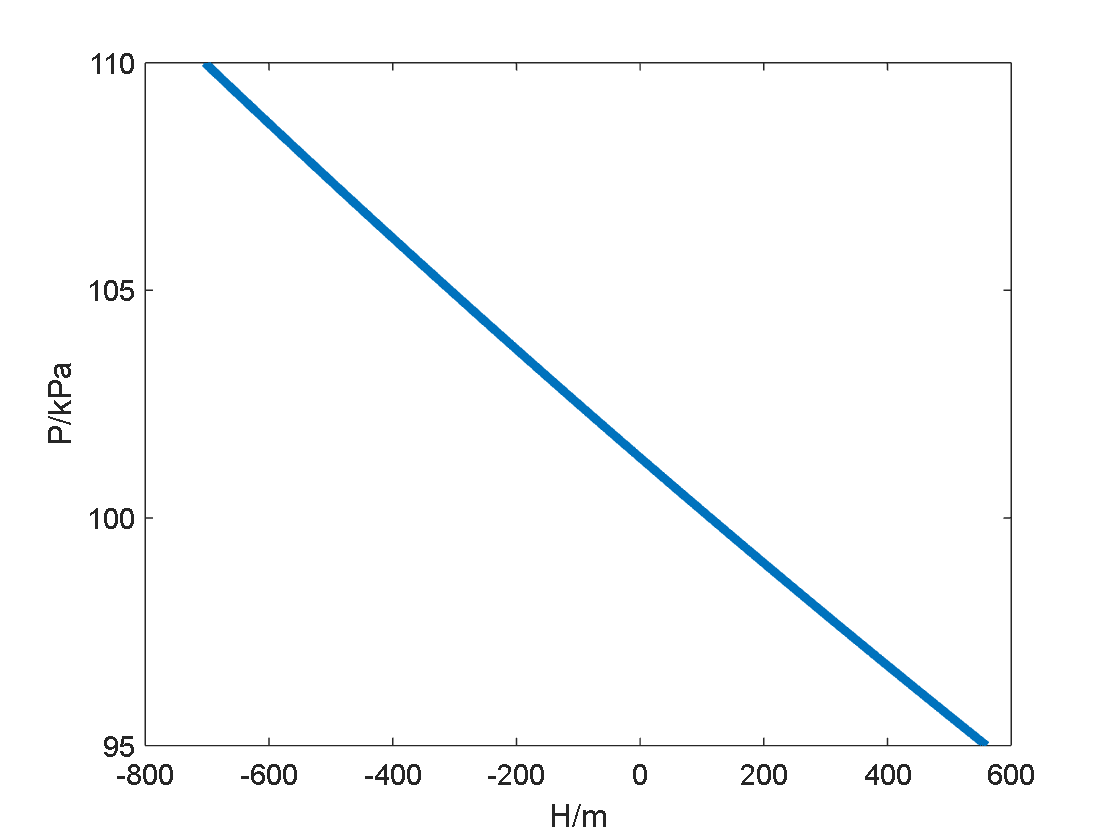

plot(h1,P,'LineWidth',3);
ylabel('P/kPa');
xlabel('H/m')
hold on

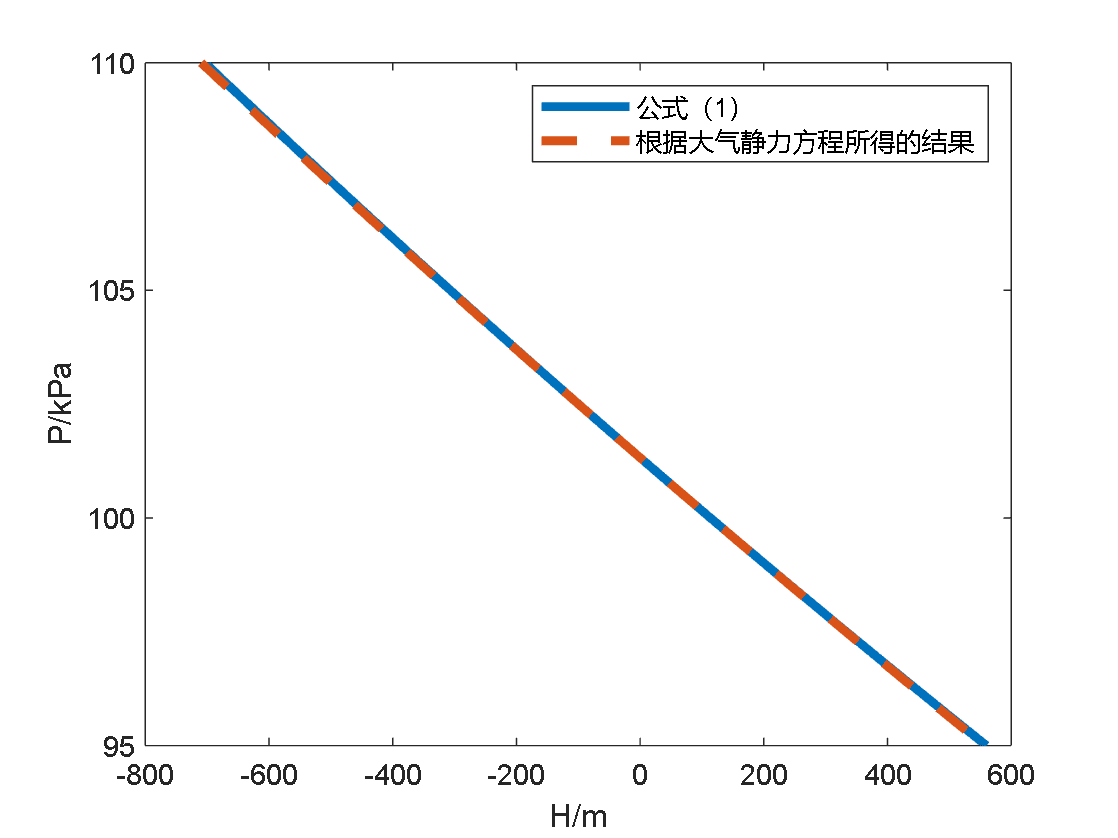

R=287.05;
g=9.8;
h2=-R*T_0/g*log(P./101.325);
plot(h2,P,'LineWidth',3,"LineStyle","--");
legend('公式（1）','根据大气静力方程所得的结果')